net = load("net.mat").net()

net =   DAGNetwork with properties:

         Layers: [71×1 nnet.cnn.layer.Layer]
    Connections: [78×2 table]
     InputNames: {'data'}
    OutputNames: {'new_classoutput'}


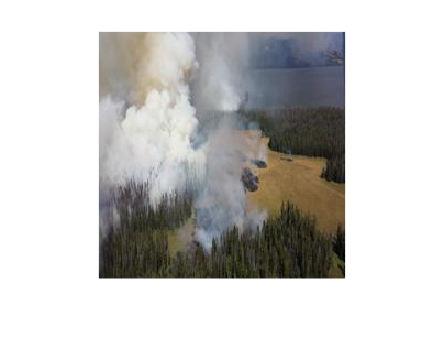

folder = "resized_dataset\fire";
allFiles = dir(folder); % Elenco di tutti i file nella cartella
fileList = allFiles(contains({allFiles.name}, {'.png', '.jpg'}));
randomIndex = randi(length(fileList), 1, 1); % Get random number.;
fullFileName = fullfile(folder, fileList(randomIndex).name);
img = imread(fullFileName);
imshow(img)

predicted = net.predict(img);
if predicted(1) > predicted(2)
    disp("Incendio rilevato")
else
    disp("Incendio non rilevato")
end

Incendio rilevato


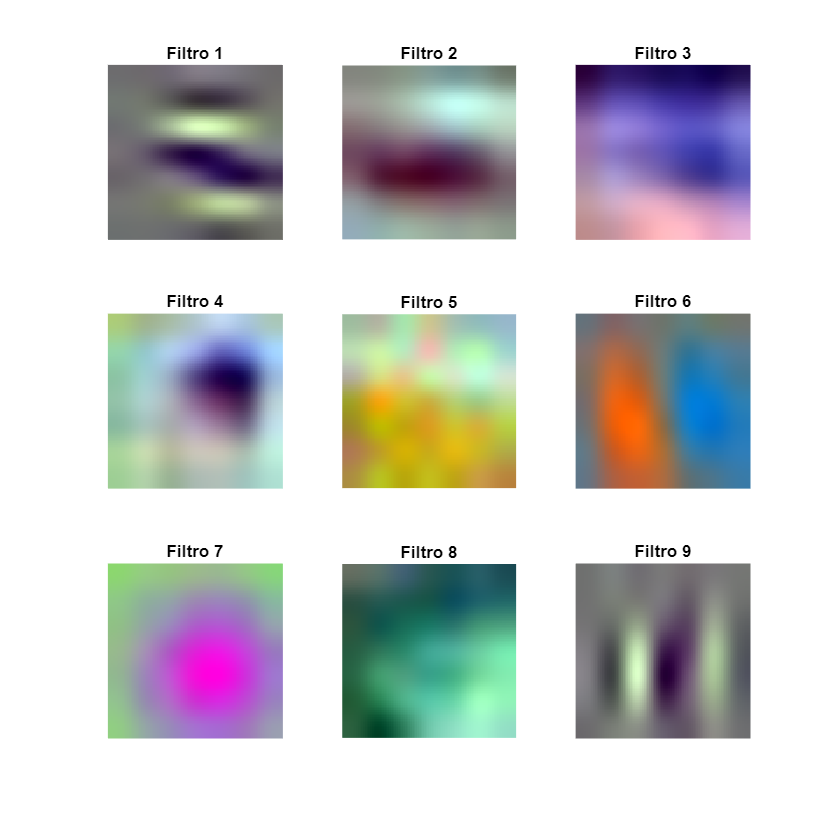

%Ottieni i pesi del livello "conv1"
conv1_weights = net.Layers(2).Weights; % supponiamo che conv1 sia il secondo layer

% Seleziona i primi 9 filtri
filters = conv1_weights(:, :, :, 1:9);

% Crea una figura per visualizzare i filtri
figure;

% Cicla su ogni filtro per visualizzarlo in formato RGB
for i = 1:9
    subplot(3, 3, i); % Disporre in una griglia 3x3
    filter = filters(:, :, :, i);
    
    % Normalizza il filtro per visualizzarlo correttamente
    filter = mat2gray(filter);
    
    % Resize del filtro a 100x100
    filter_resized = imresize(filter, [100 100]);
    
    % Visualizza il filtro
    imshow(filter_resized, 'InitialMagnification', 'fit');
    title(['Filtro ' num2str(i)]);
end

% Imposta la finestra della figura per essere più grande
set(gcf, 'Position', [100, 100, 900, 900]);

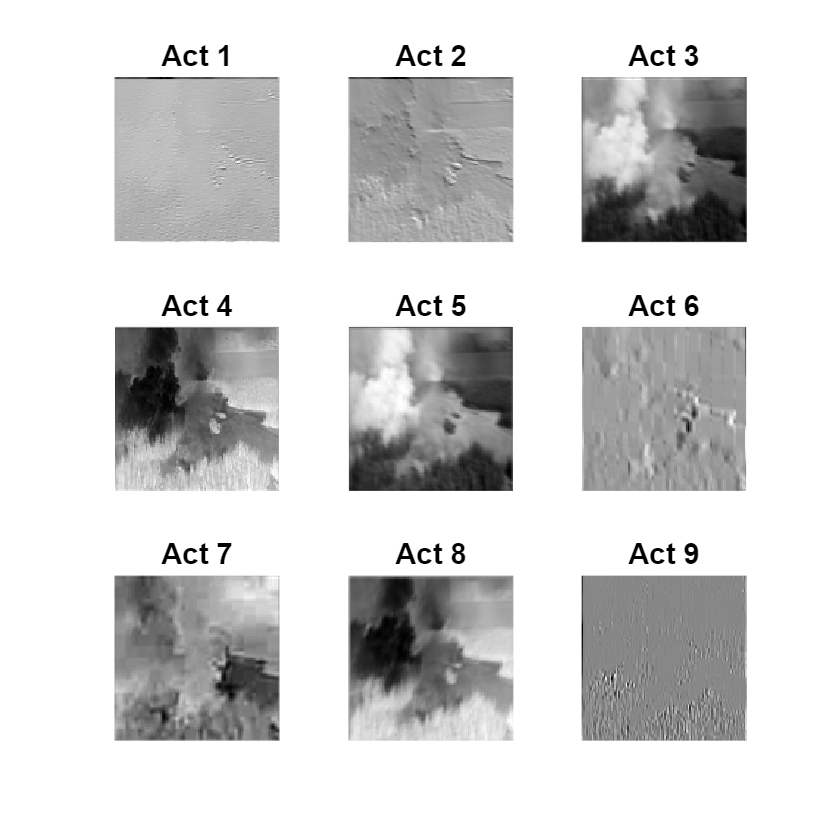

activationsOutput = activations(net, img, "conv1");

numFilters = size(activationsOutput, 3);

% Determina quanti filtri visualizzare (ad esempio, massimo 10)
numToShow = min(numFilters, 9);

% Crea una figura grande
figure('Units', 'pixels', 'Position', [100, 100, 1500, 1500]); % Figura grande con dimensioni specifiche

% Mostra le attivazioni
for i = 1:numToShow
    % Creare un subplot con dimensioni adeguate
    subplot(ceil(sqrt(numToShow)), ceil(sqrt(numToShow)), i);
    
    % Visualizza l'attivazione del filtro i
    imagesc(activationsOutput(:, :, i)); 
    colormap gray; % Applica una scala di grigi
    axis off; % Rimuovi gli assi
    axis image; % Mantieni la corretta proporzione dell'immagine
    title(['Act ', num2str(i)], 'FontSize', 16); % Aumenta la dimensione del titolo per leggibilità
end